% 9 hz center row 9 canopy elements, consider the buoyancy force

ForceB9Center = [0.00796219,0.00908807,0.00433309,0.00280036,0.00200288,0.00132192,0.000956794,0.000799083,0.000747537];

% 9 hz center row 9 canopy elements, without consider the buoyancy force

ForceWB9Center = [0.00728497,0.00831948,0.00395613,0.00255419,0.00182626,0.00120506,0.000872264,0.000728403,0.000681401];

% 9 hz nearest row 9 canopy elements, without consider the buoyancy force

ForceB9nearest = [0.0101124,0.00701823,0.00329245,0.00294483,0.00216897,0.00157587,0.00149487,0.00147579,0.00140393];

% 9 hz nearest row 9 canopy elements, consider the buoyancy force

ForceWB9nearest = [0.00926448,0.00641788,0.00300605,0.0026884,0.00198029,0.00143764,0.00136603,0.001348,0.00128311];

h = figure(1)

h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


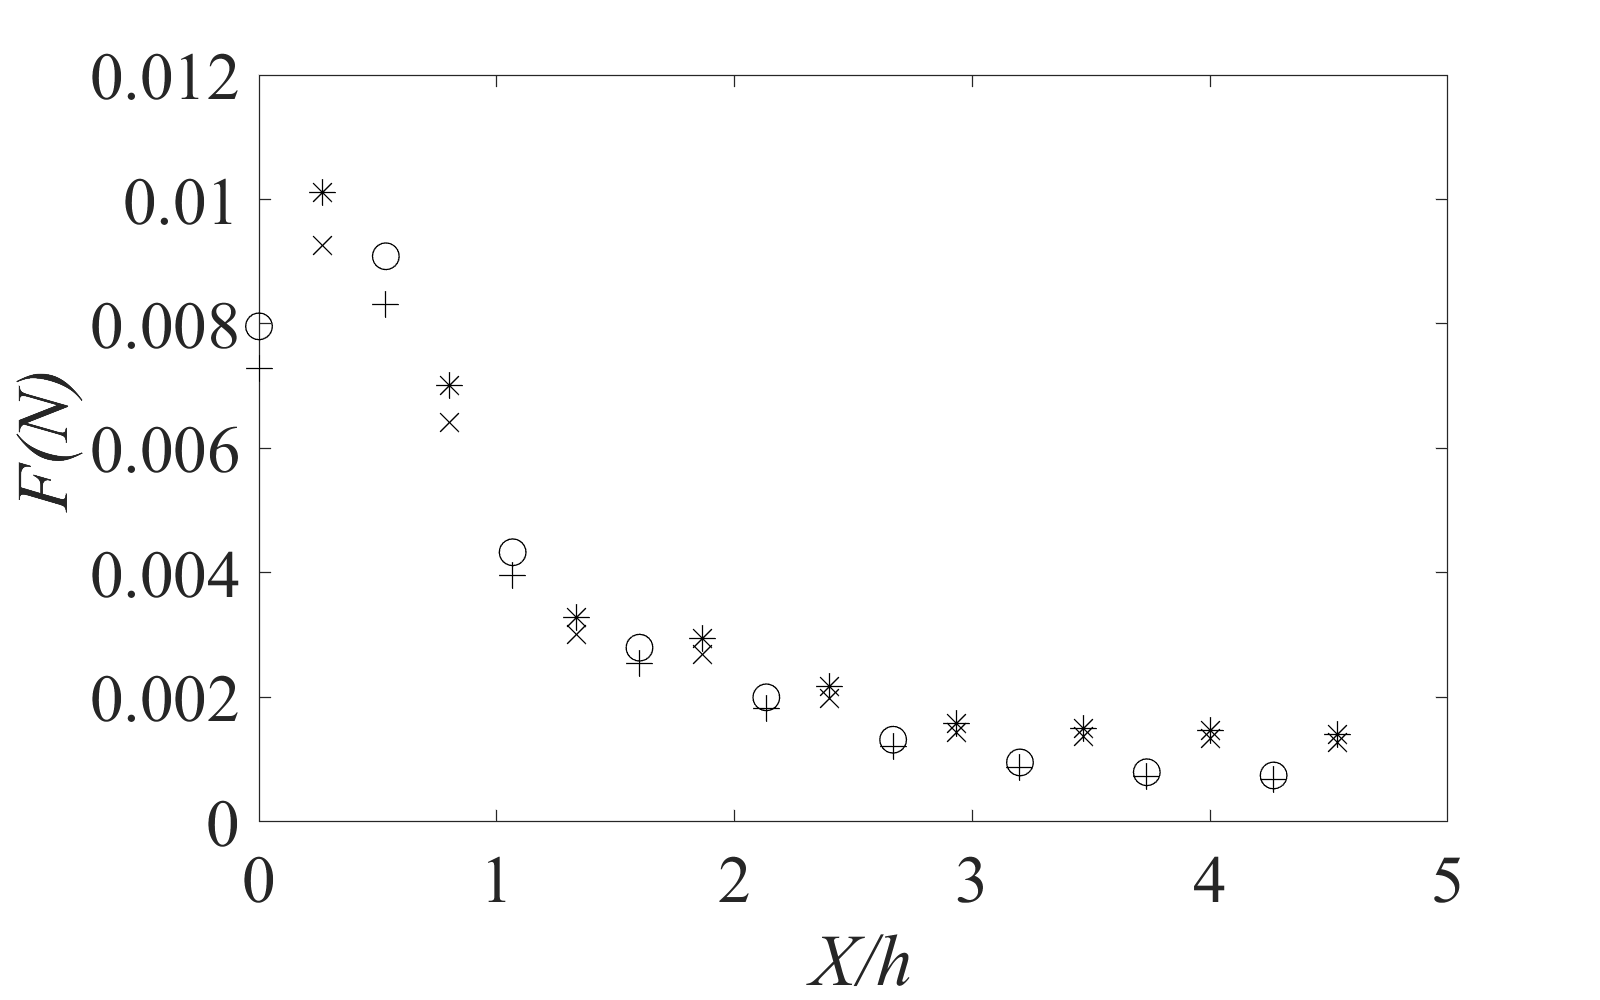

xnearest = [];
for i = 1:9
    xnearest = [xnearest, 10 + (i-1) * 20];
end
xcenter = [];
for i = 1:9
    xcenter = [xcenter, (i-1) * 20];
end
xcenter = xcenter/37.5;
xnearest = xnearest/37.5;
xintCenter = linspace(xcenter(1),xcenter(9),100);
xintNearest = linspace(xnearest(1),xnearest(9),100);
spl = spline(xcenter,ForceB9Center);
plot(xcenter,ForceB9Center,'o','color','black','MarkerSize',10);
hold on
plot(xcenter,ForceWB9Center,'+','color','black','MarkerSize',10);
hold on
plot(xnearest,ForceB9nearest, '*','color','black','MarkerSize',10);
hold on
plot(xnearest,ForceWB9nearest,'x','color','black','MarkerSize',10);
xlabel('{\it X/h}');
ylabel('{\it F(N)}');
set(h,'Position',[100, 100, 800, 500])
set(gca, 'FontName', 'Times New Roman')
set(gca, 'FontSize', 25)